close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

**a) Is it a convex problem? Why?**

Yes, the function is convex 

f_1 = @(x1,x2) 3*x1^2 + x2^2 - 2*x1*x2 + exp(x1+x2);

x1 = linspace(-30,30, 100);
x2 = linspace(-30,30, 100);
[X1,X2] = meshgrid(x1,x2);

F1 = f_1(X1,X2);

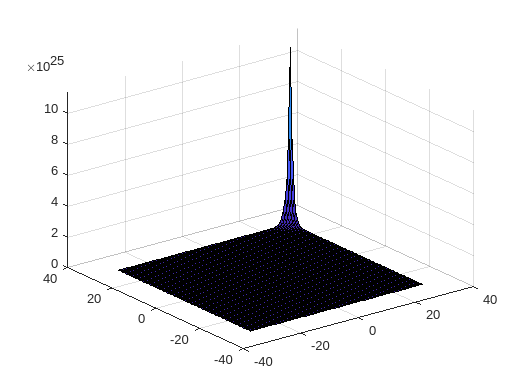

% 3D
figure;
surf(X1,X2,F1);

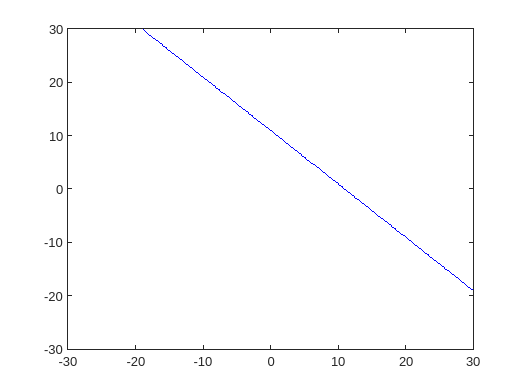

% 2D
figure;
contour(X1,X2,F1, [0 0], 'EdgeColor',"b");

**b) Do global minima exist? Why?**

Yes, weistrass theorem. because the objective function is continuous and there exist some not empty Sublevel alpha that creates a feasible region closed and bounded.

**c) Is the global minimum unique? Why?**

**d) Solve the problem by means of the gradient method with Armijo inexact line search setting**

**alpha = 0.1, gamma = 0.9, tbar= 1, starting from the point (10, 10) and using norm(g(x)) < 1e-6 as stopping criterion. What is the global minimum? How many iterations are needed?**

syms x1 x2
objectiveFunction = 3*x1^2 + x2^2 - 2*x1*x2 + exp(x1+x2);
    
    
% Differentiate with respect to x1, x2, lambda1, lambda2
d_x1 = diff(objectiveFunction, x1);
d_x2 = diff(objectiveFunction, x2);
g = [d_x1
     d_x2];

dd_x1 = diff(d_x1,x1);
dd_x2 = diff(d_x2,x2);
dd_x1x2 = diff(d_x1,x2);

H = [dd_x1 dd_x1x2
     dd_x1x2 dd_x2]

$$H = \left(\begin{array}{cc} {\mathrm{e}}^{x_{1}+x_{2}}+6 & {\mathrm{e}}^{x_{1}+x_{2}}-2\\ {\mathrm{e}}^{x_{1}+x_{2}}-2 & {\mathrm{e}}^{x_{1}+x_{2}}+2 \end{array}\right)$$

x0 = [10
      10]

x0 =     10
    10


alpha = 0.1

alpha = 0.1000

gamma = 0.9

gamma = 0.9000

tbar = 1

tbar = 1


tolerance = 1e-6;

x = x0;
i = 0;

[v,g] = f(x);

fprintf("i \t f(x) \t \t \t norm(g) \n");

i 	 f(x) 	 	 	 norm(g) 


fprintf("%5.0f  %2.13f  %2.13f \n", i, v, norm(g));

    0  485165395.4097902774811  686127227.6241900920868 


while (norm(g)>=tolerance)
    d = -g;
    t = tbar;

    while f(x+t*d) > f(x) + alpha*t*d'*g
        t = gamma*t;
    end

    x = x + t*d;
    i = i+1;
    fprintf("%5.0f  %2.13f  %2.13f \n", i, v, norm(g));
    [v,g] = f(x);

end

    1  485165395.4097902774811  686127227.6241900920868 
    2  35091.8689188574281  49564.7704467924123 
    3  5.1492532768727  8.1152596974172 
    4  3.0276166612624  5.7067379145424 
    5  2.0413381831628  4.3954957268793 
    6  1.4989662653304  3.4105442363442 
    7  1.1569808698210  2.6394245689402 
    8  0.9620585313699  2.0518850154173 
    9  0.8404414823612  1.5918431133085 
   10  0.7694433947918  1.2382127707553 
   11  0.7255879565205  0.9617501319707 
   12  0.6996110290839  0.7481623704459 
   13  0.6836850802594  0.5814559432013 
   14  0.6741707936479  0.4523005032336 
   15  0.6683672975251  0.3516215488013 
   16  0.6648828988729  0.2734974729877 
   17  0.6627644258546  0.2126513972837 
   18  0.6614887632205  0.1653938977407 
   19  0.6607147615388  0.1286087493517 
   20  0.6602478759475  0.1000237299951 
   21  0.6599649534800  0.0777811486738 
   22  0.6597941145213  0.0604915327442 
   23  0.6596906699747  0.0470411109587 
   24  0.6596281674692  0.0365839

**e) Solve the problem by means of the Newton method with Armijo inexact line search setting**

**alpha = 0.1, gamma = 0.9, tbar= 1, starting from the point (10, 10) and using norm(g(x)) 1e-6 as stopping criterion. What is the global minimum? How many iterations are needed?**

x0 = [10
      10]

x0 =     10
    10


alpha = 0.1

alpha = 0.1000

gamma = 0.9

gamma = 0.9000

tbar = 1

tbar = 1


tolerance = 1e-6;

x = x0;
i = 0;

[v,g,H] = f(x);
fprintf("i \t f(x) \t \t \t norm(g) \n");

i 	 f(x) 	 	 	 norm(g) 


fprintf("%5.0f  %2.3f  %2.3f \n", i, v, norm(g));

    0  485165395.410  686127227.624 


while (norm(g)>=tolerance)
    d = -H\g;
    t = tbar;
    while f(x+t*d)> f(x) + alpha*t*d'*g
        t = gamma*t;
    end
    x = x + t*d;
    i = i+1;
    fprintf("%5.0f  %2.13f  %2.13f \n", i, v, norm(g));
    [v,g, H] = f(x);
end

    1  485165395.4097902774811  686127227.6241900920868 
    2  178482416.6367137432098  252412101.9891061186790 
    3  65660071.0085293278098  92857227.1621421426535 
    4  24155042.6629462204874  34160268.7254904806614 
    5  8886189.5665447134525  12566864.2082231771201 
    6  3269086.3806975483894  4623094.3722942862660 
    7  1202663.9796750214882  1700744.5151319811121 
    8  442464.4629419718403  625671.8336487631314 
    9  162797.9122866647667  230174.4472502240969 
   10  59909.9819506272543  84678.8406559896248 
   11  22055.6928222983261  31153.7491366953072 
   12  8126.3641428314531  11462.7193593285192 
   13  2998.9568386577043  4218.5453898850565 
   14  1110.0147051310828  1553.3138710142809 
   15  412.8548810902250  572.5811191490232 
   16  154.5426119661962  211.5402549073893 
   17  58.0875140272199  78.4689318082874 
   18  21.5958459314370  29.2560289387527 
   19  7.6075342254096  10.8781931120095 
   20  2.3925054956191  3.8327290284700 
   21  0.856016

function [v,g, H] = f(x)
    x1 = x(1);
    x2 = x(2);
    % Define the Objective Function and the Constraints
    v = 3*x1^2 + x2^2 - 2*x1*x2 + exp(x1+x2);
    g = [6*x1 - 2*x2 + exp(x1+x2)
         2*x2 - 2*x1 + exp(x1+x2)];  
    H = [(exp(x1+x2)+6) (exp(x1+x2)-2)
         (exp(x1+x2)-2) (exp(x1+x2)+2)];
end